# FEM HW6

## Problem 1.1

## Verify your code is working for the steady-state, advection-diffusion case

All functions below are implemented under folder 'HW6_Test_Problems/HW6_Test_Problem_1'

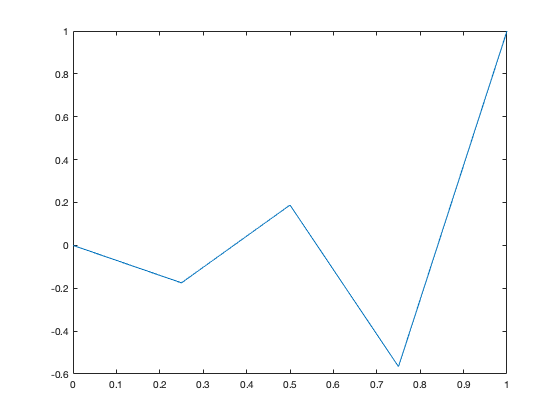

% Mesh 1
Globalad(); 
hold on

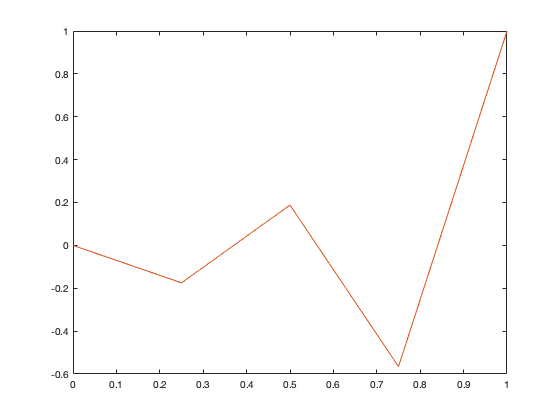

% Mesh 2
Globalad();

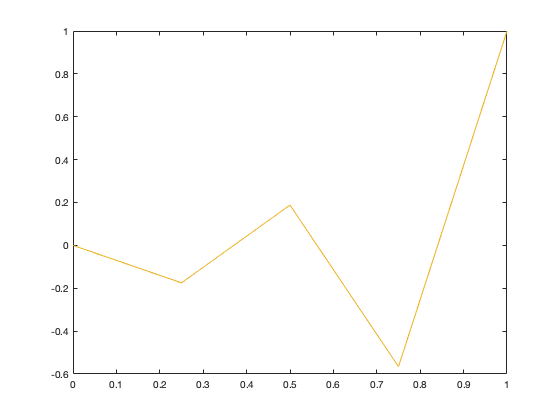

% Mesh 3
Globalad();

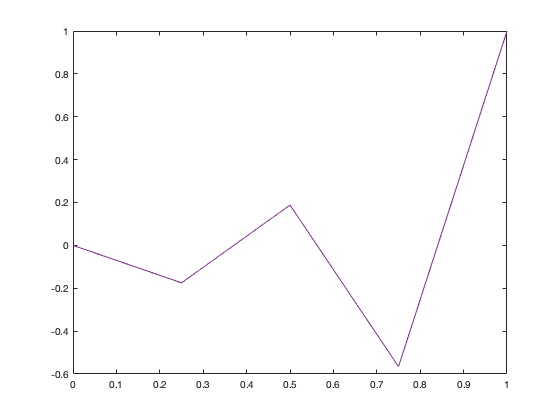

% Mesh 4
Globalad();

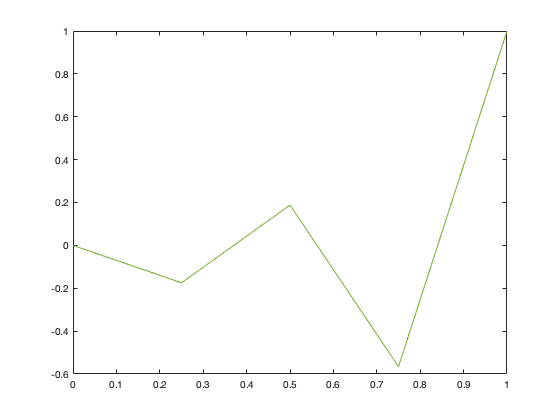

% Mesh 5
Globalad();

## Problem 1.2

## Provide calculations showing how many refinements of the first mesh

## are needed before non-oscillatory behavior is observed.

## Verify your estimate is correct by using the series of uniformly re-

## fined meshes provided.

Since$Pe = \frac{ch}{2k}
$ and $\frac{c}{k}$ = 40, $Pe = 20h$.  

With 3 elements in the initial mesh, the initial value of $h$ is $\frac{1}{3}$ and initial value of $Pe = \frac{20}{3}$.

$Pe$ has to be less than $1$ to avoid oscillation. Every refinement in the mesh will half $h$ and $Pe$ will be halved as well. To force $Pe$ to be less than 1,  4 refinements are need according to the calculation below.

for i=1:10
    if 20/3*(1/2)^i<1
        break;
    end
end
i+1 % counting the first mesh

% 'HW6_Test_Problems/HW6_Test_Problem_2/Mesh4
Globalad(); 

As the picture has shown, the oscillation behavior has disappeared.

## Problem 1.3

% alpha = 0
FEMHW6P3

% alpha = 1
FEMHW6P3

% alpha = 0.5
FEMHW6P3

% alpha = 0.25
FEMHW6P3

% alpha = 0.23
FEMHW6P3